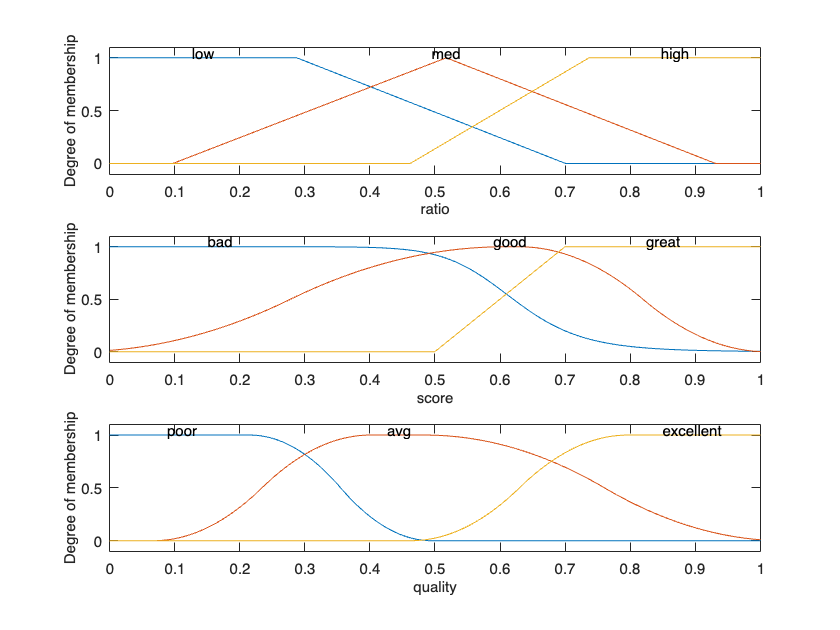

% Create FIS
qualityFIS = mamfis(...
    'Name', 'Fuzzy Prioritizing', ...
    'NumInputs', 2, 'NumInputMFs', 3, ...
    'NumOutputs', 1, 'NumOutputMFs', 3, ...
    'AddRule','none'...
    );

% Update Input

qualityFIS.Inputs(1).Name = 'ratio';
qualityFIS.Inputs(1).Range = [0,1];
qualityFIS.Inputs(1).MembershipFunctions(1).Name = 'low';
qualityFIS.Inputs(1).MembershipFunctions(1).Type = 'linzmf';
qualityFIS.Inputs(1).MembershipFunctions(1).Parameters = [0.287746 0.700362];
qualityFIS.Inputs(1).MembershipFunctions(2).Name = 'med';
qualityFIS.Inputs(1).MembershipFunctions(2).Type = 'trimf';
qualityFIS.Inputs(1).MembershipFunctions(2).Parameters = [0.0974829 0.51727 0.93082];
qualityFIS.Inputs(1).MembershipFunctions(3).Name = 'high';
qualityFIS.Inputs(1).MembershipFunctions(3).Type = 'linsmf';
qualityFIS.Inputs(1).MembershipFunctions(3).Parameters = [0.462069 0.736569];

% Update Input

qualityFIS.Inputs(2).Name = 'score';
qualityFIS.Inputs(2).Range = [0,1];
qualityFIS.Inputs(2).MembershipFunctions(1).Name = 'bad';
qualityFIS.Inputs(2).MembershipFunctions(1).Type = 'gbellmf';
qualityFIS.Inputs(2).MembershipFunctions(1).Parameters = [0.624384 5.80607 -0.0041365];
qualityFIS.Inputs(2).MembershipFunctions(2).Name = 'good';
qualityFIS.Inputs(2).MembershipFunctions(2).Type = 'pimf';
qualityFIS.Inputs(2).MembershipFunctions(2).Parameters = [-0.0524819 0.6083 0.6288 1.01];
qualityFIS.Inputs(2).MembershipFunctions(3).Name = 'great';
qualityFIS.Inputs(2).MembershipFunctions(3).Type = 'linsmf';
qualityFIS.Inputs(2).MembershipFunctions(3).Parameters = [0.499627 0.699627];

% Update Output

qualityFIS.Outputs(1).Name = 'quality';
qualityFIS.Outputs(1).Range = [0,1];
qualityFIS.Outputs(1).MembershipFunctions(1).Name = 'poor';
qualityFIS.Outputs(1).MembershipFunctions(1).Type = 'pimf';
qualityFIS.Outputs(1).MembershipFunctions(1).Parameters = [-0.375 -0.04167 0.215517 0.494663];
qualityFIS.Outputs(1).MembershipFunctions(2).Name = 'avg';
qualityFIS.Outputs(1).MembershipFunctions(2).Type = 'pimf';
qualityFIS.Outputs(1).MembershipFunctions(2).Parameters = [0.0675287 0.400829 0.484229 1.03654];
qualityFIS.Outputs(1).MembershipFunctions(3).Name = 'excellent';
qualityFIS.Outputs(1).MembershipFunctions(3).Type = 'pimf';
qualityFIS.Outputs(1).MembershipFunctions(3).Parameters = [0.462963 0.796263 1.01736 1.21296];

subplot(3, 1, 1);
plotmf(qualityFIS, 'input', 1, 1000);
subplot(3, 1, 2);
plotmf(qualityFIS, 'input', 2, 1000);
subplot(3, 1, 3);
plotmf(qualityFIS, 'output', 1, 1000);

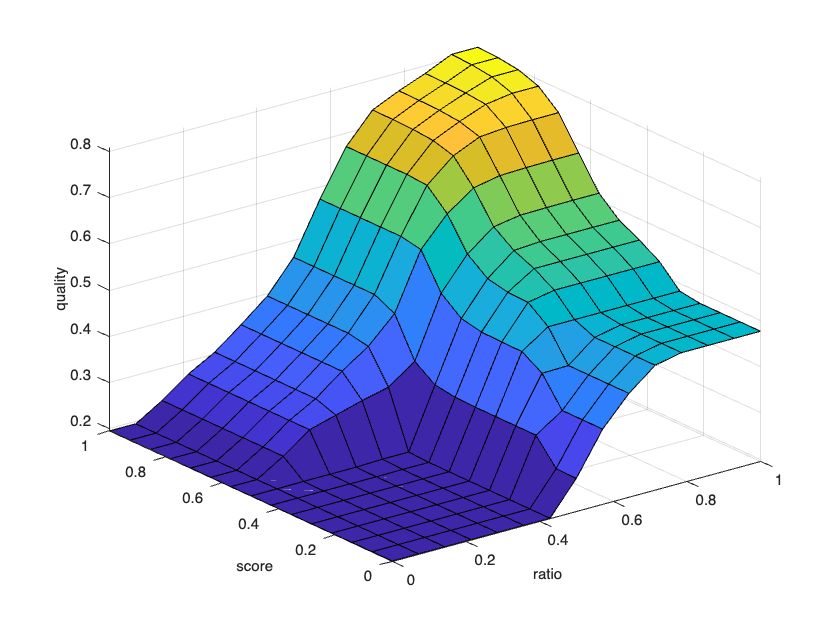

% Specify Rules


rules = [...
    "If ratio is low or score is bad then quality is poor (0.6)"; ...
    "If ratio is med and score is great then quality is avg (0.3)"; ...
    "If ratio is high and score is great then quality is excellent (1)"; ...
    "If ratio is high and score is bad then quality is excellent (0.5)";
    "If ratio is high and score is good then quality is excellent (1)"...
    ];
figure
qualityFIS = addRule(qualityFIS, rules);
gensurf(qualityFIS)

testData = [...
    0.77, 0.32; ...
    0.64, 0.90; ...
    ];
testData2 = [...
    0.77, 0.94; ...
    1, 0.65; ...
    ];

inputNames = {'ratio', 'score'};
outputName = 'quality';

% Display the test data
disp('Test Data:');

Test Data:




qualityFIS = readfis('quality');
output = evalfis(qualityFIS, testData);

% Display the results
disp('Results:');

Results:


disp([inputNames, outputName]);

    {'ratio'}    {'score'}    {'quality'}



disp([num2cell(testData), num2cell(output)]);

    {[0.7700]}    {[0.3200]}    {[0.5069]}
    {[0.6400]}    {[0.9000]}    {[0.6685]}



qualityFIS = readfis('quality');
output = evalfis(qualityFIS, testData2);
disp('Results:');

Results:


disp([inputNames, outputName]);

    {'ratio'}    {'score'}    {'quality'}



disp([num2cell(testData2), num2cell(output)]);

    {[0.7700]}    {[0.9400]}    {[0.7566]}
    {[     1]}    {[0.6500]}    {[0.6884]}

